# Advection driver 2

This driver tests advection with $sin^4(\pi x)$ on $[-1,1]$ with periodic boundary

#### Setup Parameters

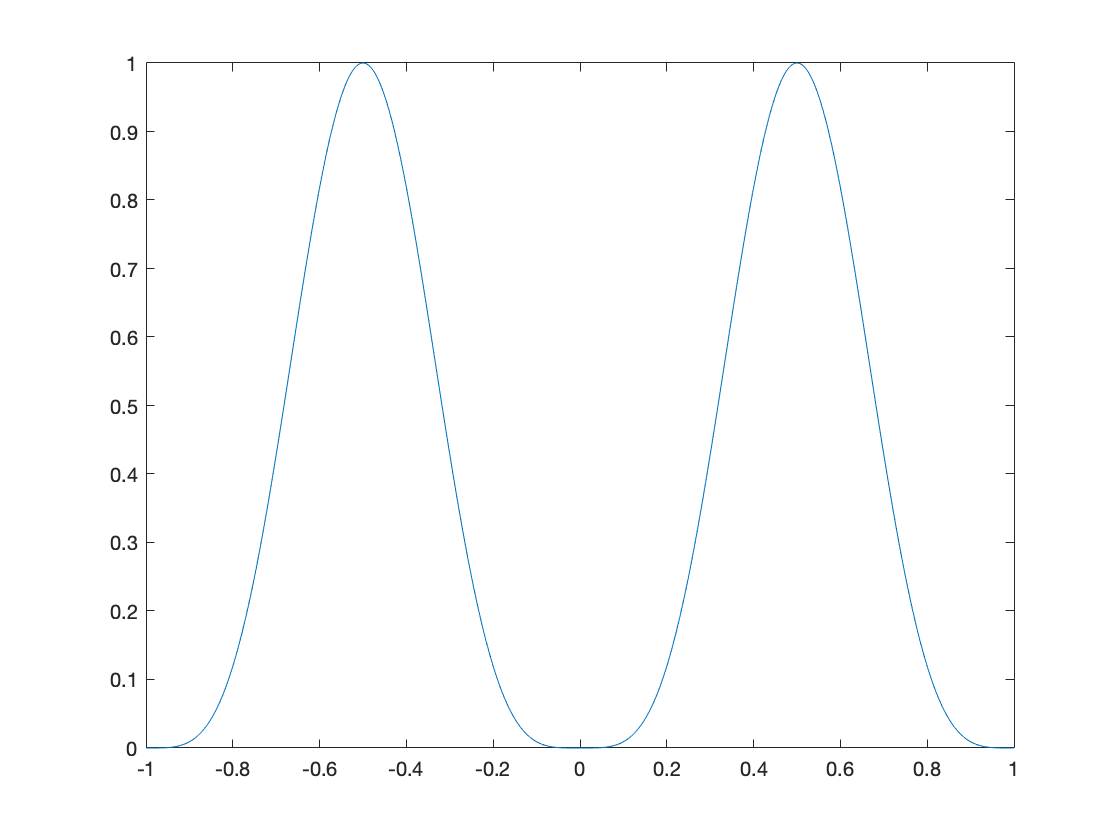

Nx = 2^12;
Nt = 2^13;
h = 2/Nx;
x = linspace(-1,1,Nx+1);
x = x(1:end-1);
l = Nx;
y = sin(pi*x).^4;
hold off
plot(x,y)

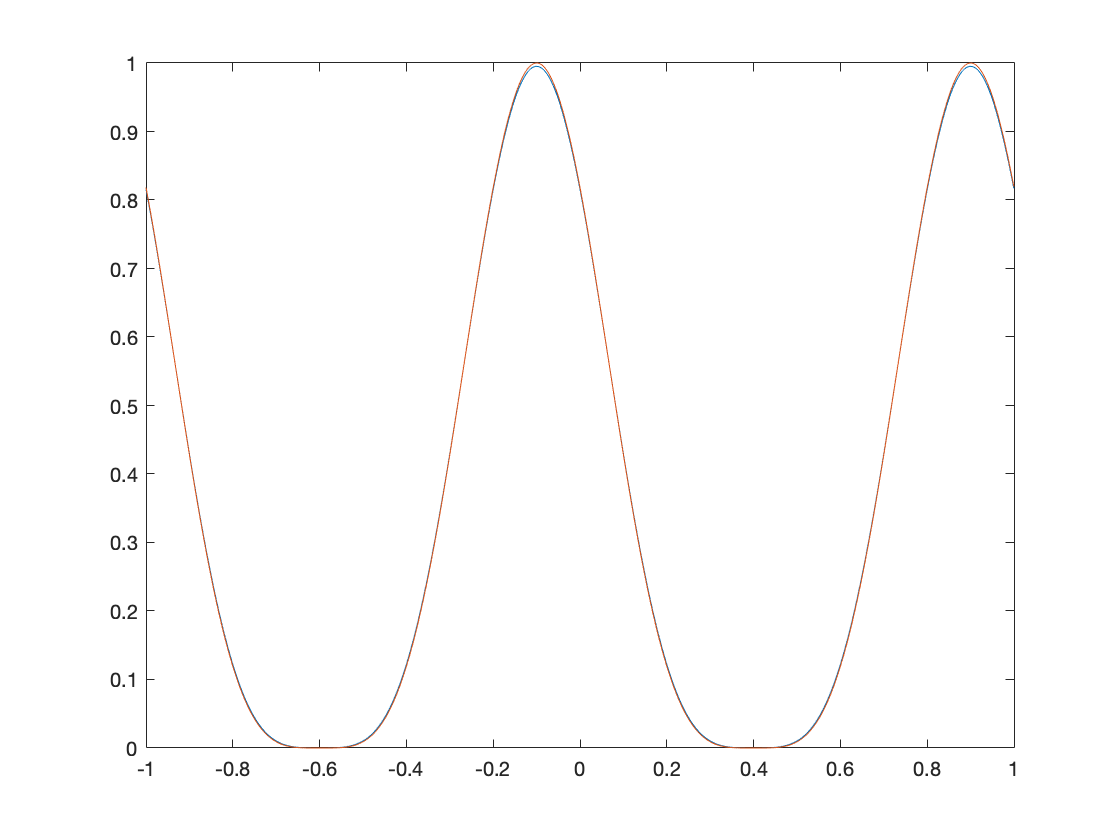

figure;
cmax = 1;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
for i = 1:Nt
    y = ERK1_U1(y, h, dt);
end
plot(x, y)
hold on
T = dt * Nt;
z = sin(pi*(x-T)).^4;
plot(x,z)
hold off

error = sqrt(h*dt)*norm(y-z)

error = 7.0379e-05

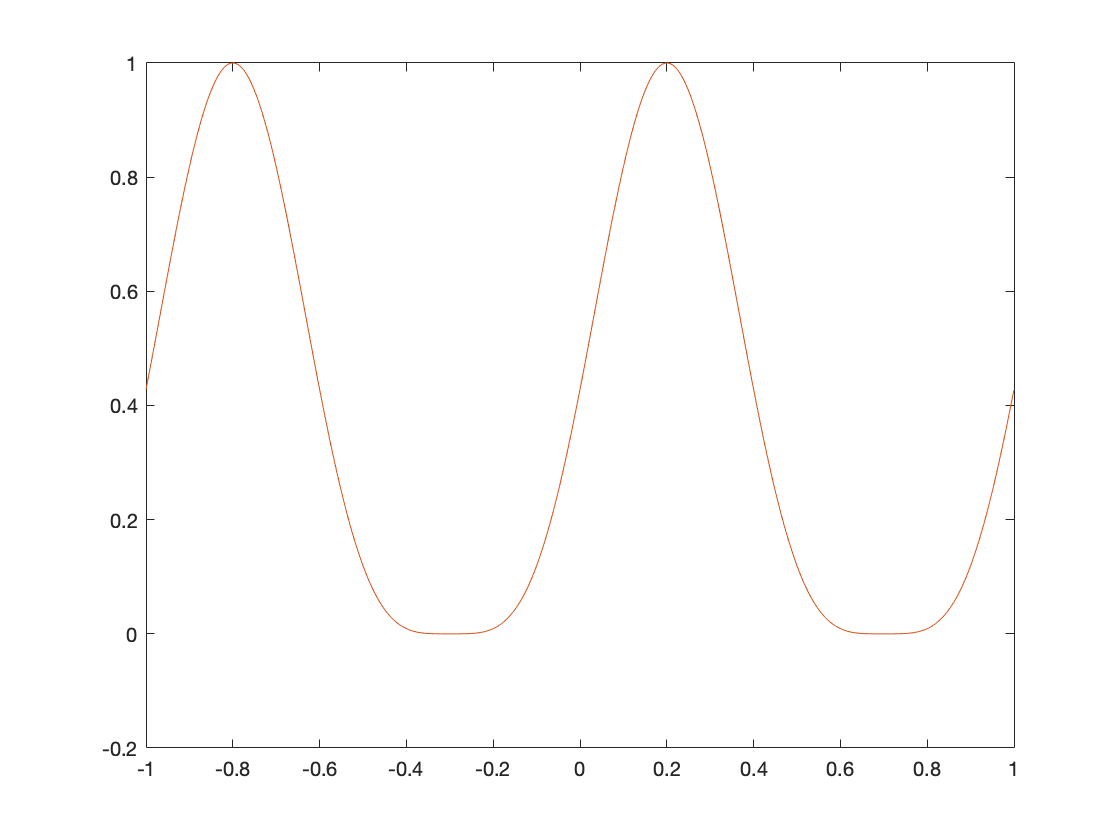

figure;
cmax = 0.5;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
for i = 1:Nt
    y = ERK2_U2(y, zeros(1,l), h, dt);
end
plot(x, y)
hold on
T = dt * Nt;
z = sin(pi*(x-T)).^4;
plot(x,z)
hold off

error = sqrt(h*dt)*norm(y-z)

error = 5.8849e-07

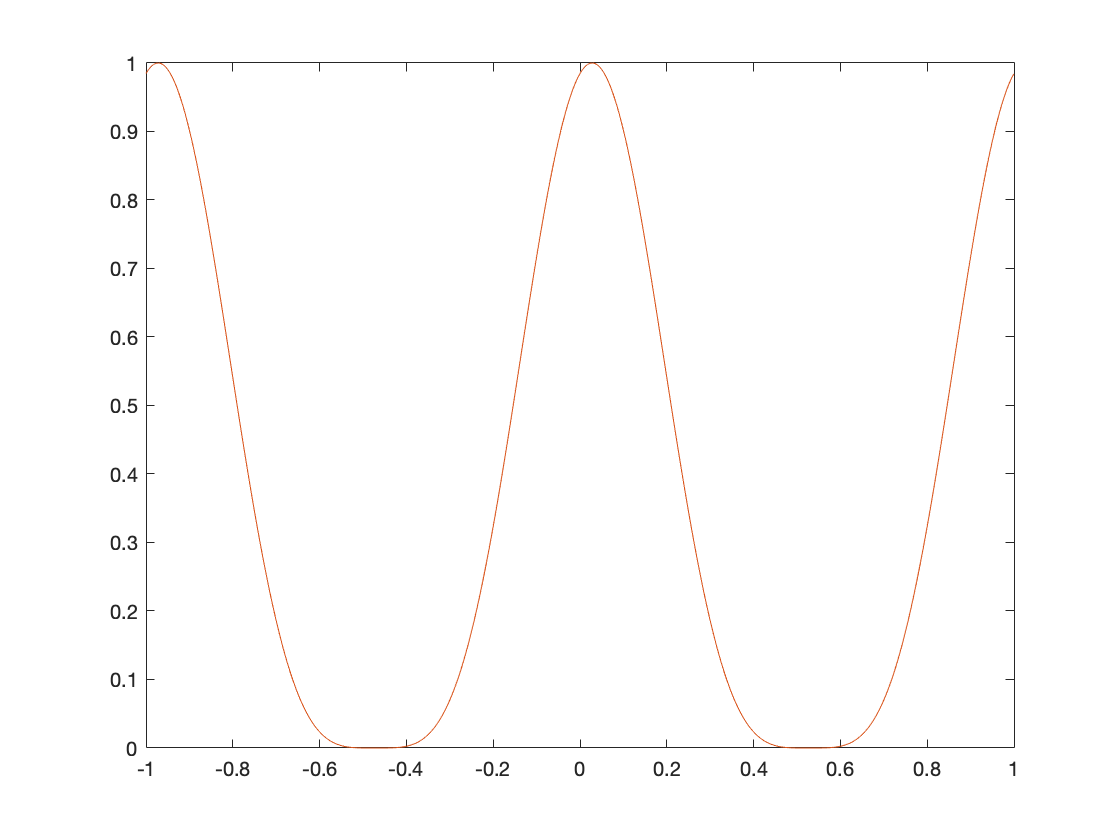

figure;
cmax = 1.62589;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
for i = 1:Nt
    y = ERK3_U3(y, h, dt);
end
plot(x, y)
hold on
T = dt * Nt;
z = sin(pi*(x-T)).^4;
plot(x,z)
hold off

error = sqrt(h*dt)*norm(y-z)

error = 1.0383e-08

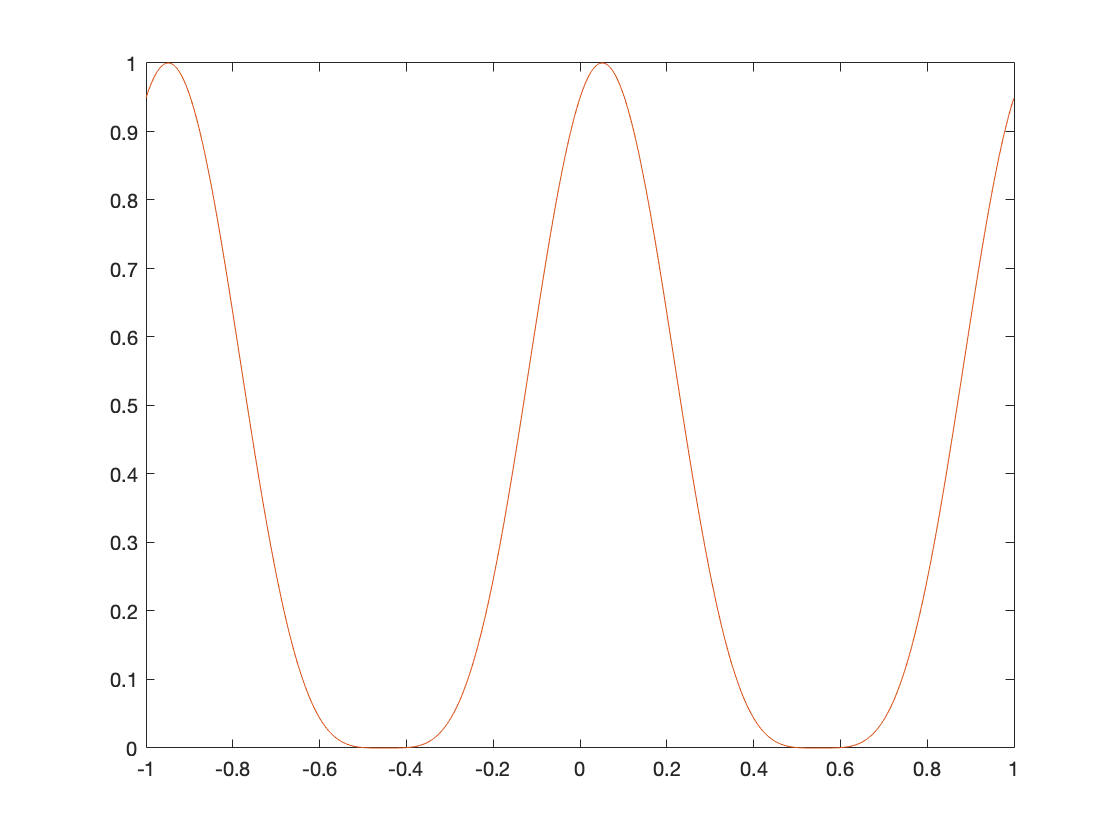

figure;
cmax = 1.04449;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
for i = 1:Nt
    y = ERK4_U4(y, h, dt);
end
plot(x, y)
hold on
T = dt * Nt;
z = sin(pi*(x-T)).^4;
plot(x,z)
hold off

error = sqrt(h*dt)*norm(y-z)

error = 7.4367e-12

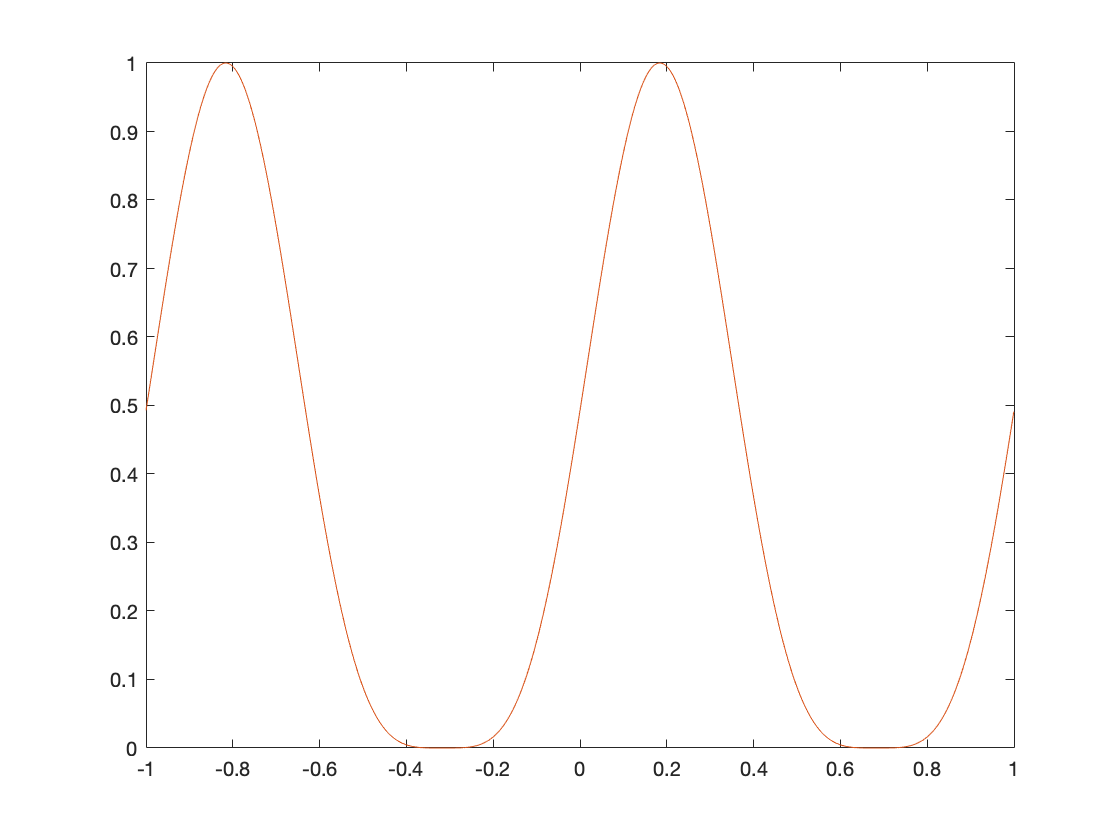

figure;
cmax = 1.96583;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
for i = 1:Nt
    y = ERK5_U5(y, h, dt);
end
plot(x, y)
hold on
T = dt * Nt;
z = sin(pi*(x-T)).^4;
plot(x,z)
hold off

error = sqrt(h*dt)*norm(y-z)

error = 2.2873e-14

cmax = 0.5;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
Y = repmat(y, Nt+1, 1);
T = dt * Nt;
seq = y;
for i = 1:Nt
    seq = Lax_Wendroff(seq, zeros(1,Nx), h, dt);
end
g = zeros(size(Y));
for iter = 1:16
    Y = MGRIT_explicit(Y, g, h, dt, @advection_explicit, 16, 2);
    disp(strcat('error = ',string(norm(seq-Y(end,:)))))
    error_MGRIT(iter) = norm(seq-Y(end,:));
end

error =0.0018658
error =2.028e-07
error =8.7307e-11
error =2.3852e-10
error =5.1289e-10
error =7.1479e-10
error =5.272e-10
error =8.7161e-11
error =2.4117e-13
error =1.3767e-13
error =9.7084e-14
error =7.6381e-14
error =5.0982e-14
error =4.0033e-14
error =5.1304e-15
error =0


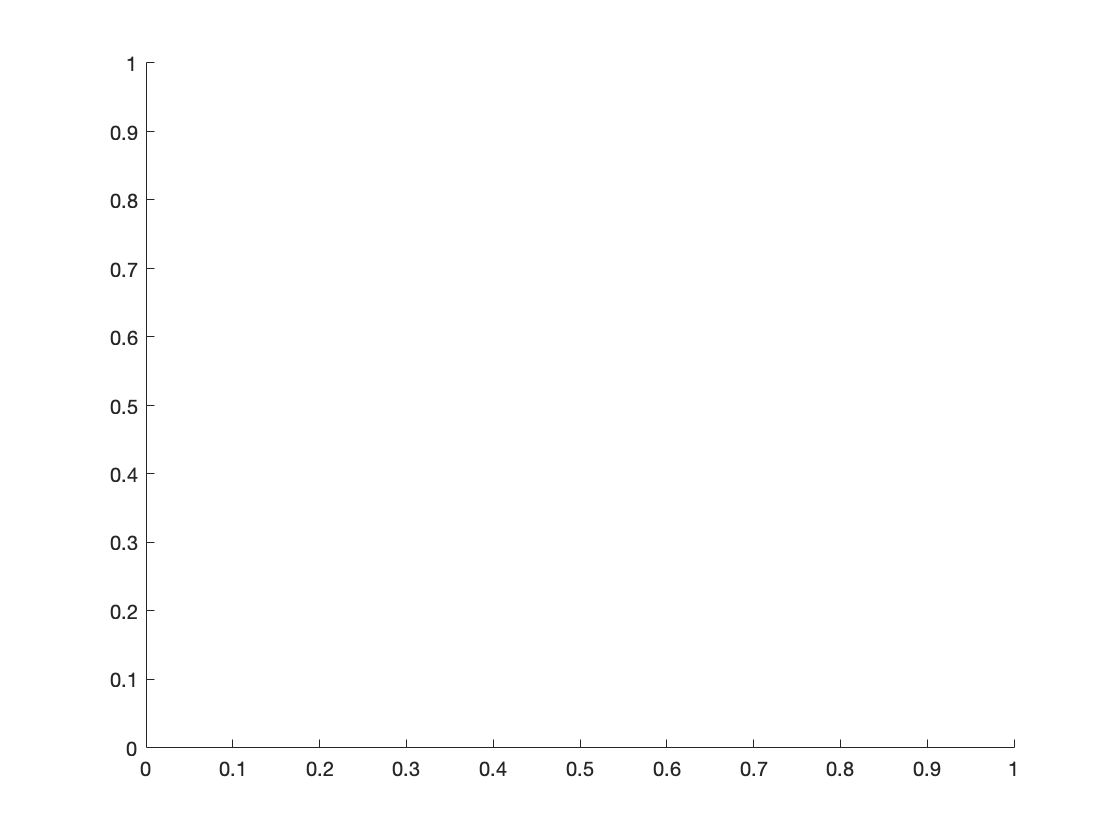

error = 0.0014879
error = -0.0016962
error = -0.0016961
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962
error = -0.0016962


cmax = 0.5;
dt = 0.85 * cmax * h;
y = sin(pi*x).^4;
Y = repmat(y, Nt+1, 1);
T = dt * Nt;
seq = y;
for i = 1:Nt
    seq = Lax_Wendroff(seq, zeros(1,Nx), h, dt);
end
g = zeros(size(Y));
[Y, error_mp] = multilevel_parareal(Y, g, h, dt, @advection_explicit, @linear_restriction, @ave_update_prolongation, 16, 2);